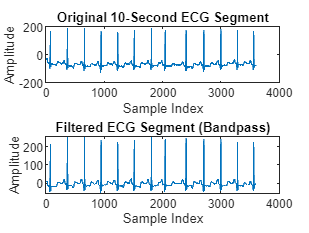

% Load the ECG data
load('100m.mat');

% Define the sampling frequency
Fs = 360; % Hz

% Define the start and end indices for the 10-second segment
start_index = 1; % Start at the beginning of the signal
end_index = start_index + 10 * Fs - 1; % Extract 10 seconds of data

% Extract the 10-second segment from the ECG signal
ecg_segment = val(1, start_index:end_index);

% Define the passband frequencies (in Hz)
low_freq = 0.5; % Lower cutoff frequency
high_freq = 50; % Upper cutoff frequency

% Design the bandpass filter using 'butter' filter design
order = 4; % Filter order
[b, a] = butter(order, [low_freq high_freq] / (Fs/2), 'bandpass');

% Apply the bandpass filter to the ECG segment
ecg_filtered = filtfilt(b, a, ecg_segment);

% Plot the original and filtered ECG segments
subplot(2,1,1);
plot(ecg_segment);
title('Original 10-Second ECG Segment');
xlabel('Sample Index');
ylabel('Amplitude');

subplot(2,1,2);
plot(ecg_filtered);
title('Filtered ECG Segment (Bandpass)');
xlabel('Sample Index');
ylabel('Amplitude');

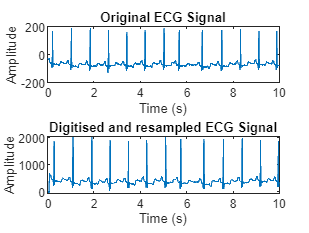

% Load a sample ECG signal
load('100m.mat')%Replace with your ECG signal data

% Define parameters
original_fs = 360; % Original sampling rate in Hz
new_fs = 360; % New sampling rate in Hz
filter_order = 50; % Filter order for artifact removal
cutoff_frequency = 50; % Cutoff frequency for artifact removal filter

% Define the start and end indices for the 10-second segment
start_index = 1; % Start at the beginning of the signal
end_index = start_index + 10* Fs - 1; % Extract 10 seconds of data

% Extract the 10-second segment from the ECG signal
ecg_data = val(1, start_index:end_index);

% Resample the ECG signal
resampled_ecg = resample(ecg_data, new_fs, original_fs);

% Digitize the resampled signal
bit_depth = 11; % Number of bits for digitization
max_value = 2^bit_depth - 1; % Maximum digital value
digitized_ecg = max_value * (resampled_ecg - min(resampled_ecg)) / (max(resampled_ecg) - min(resampled_ecg));

% Design a low-pass Butterworth filter for artifact removal
lp_filter = designfilt('lowpassfir', 'FilterOrder', filter_order, 'CutoffFrequency', cutoff_frequency, 'SampleRate', new_fs);

% Apply the filter to remove artifacts
filtered_ecg = filter(lp_filter, digitized_ecg);

% Plot the original and filtered signals
t_original = (0:length(ecg_data) - 1) / original_fs;
t_filtered = (0:length(filtered_ecg) - 1) / new_fs;

figure;
subplot(2,1,1);
plot(t_original, ecg_data);
title('Original ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t_filtered, filtered_ecg);
title('Digitised and resampled ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

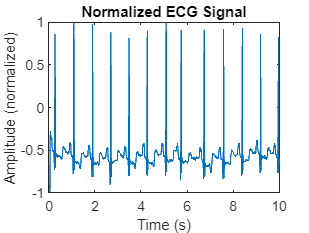

% Assuming you already have the filtered ECG signal in the 'filtered_ecg' variable

% Define the desired amplitude range for normalization (e.g., [-1, 1])
desired_min_amplitude = -1;
desired_max_amplitude = 1;

% Calculate the current minimum and maximum amplitudes in the filtered ECG signal
min_amplitude = min(filtered_ecg);
max_amplitude = max(filtered_ecg);

% Normalize the filtered ECG signal to the desired range
normalized_ecg = (filtered_ecg - min_amplitude) / (max_amplitude - min_amplitude) ...
               * (desired_max_amplitude - desired_min_amplitude) + desired_min_amplitude;

% Plot the normalized ECG signal
t_filtered = (0:length(normalized_ecg) - 1) / new_fs;

figure;
plot(t_filtered, normalized_ecg);
title('Normalized ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (normalized)');

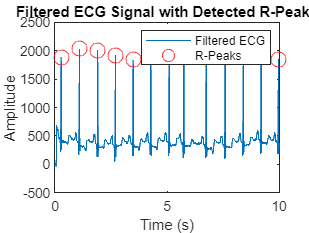

% Assuming you have the filtered ECG signal in the 'filtered_ecg' variable

% Define parameters for R-peak detection
min_distance = 0.5 * new_fs; % Minimum distance between R-peaks (adjust as needed)
threshold = 0.6; % Threshold for peak detection (adjust as needed)

% Detect R-peaks using the 'findpeaks' function
[peak_values, peak_indices] = findpeaks(filtered_ecg, 'MinPeakDistance', min_distance, 'MinPeakHeight', threshold);

% Plot the ECG signal with detected R-peaks
t_filtered = (0:length(filtered_ecg) - 1) / new_fs;

figure;
plot(t_filtered, filtered_ecg);
hold on;
plot(t_filtered(peak_indices), peak_values, 'ro', 'MarkerSize', 10);
title('Filtered ECG Signal with Detected R-Peaks');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Filtered ECG', 'R-Peaks');


% Calculate the heart rate
RR_intervals = diff(peak_indices) / new_fs; % Calculate time intervals between R-peaks
heart_rate = 60 / mean(RR_intervals); % Calculate average heart rate in beats per minute

fprintf('Average Heart Rate: %.2f bpm\n', heart_rate);

Average Heart Rate: 74.42 bpm
